# Low Code Data Analysis in MATLAB

## Step 1: Access

% Import data from spreadsheet
FlightData = readtimetable("C:\Users\ayeo\OneDrive - MathWorks\CSE_Work\Seminar\Low_Code_Data_Analysis_for_Medical_School\Examples\FlightData.xlsx", "RowTimes", "Time");

% Display results
FlightData

FlightData = 47312×13 timetable
           Time            FuelQuantity    OilPressure    OilTemperature    LatitudePosition    LongitudePosition    Altitude    ExhaustTemperature    FuelFlow    FanSpeed    TrueAirSpeed    WindDirection    WindSpeed    WeightOnWheels
    ___________________    ____________    ___________    ______________    ________________    _________________    ________    __________________    ________    ________    ____________    _____________    _________    ______________

    2001-06

## Step 2: Visualize

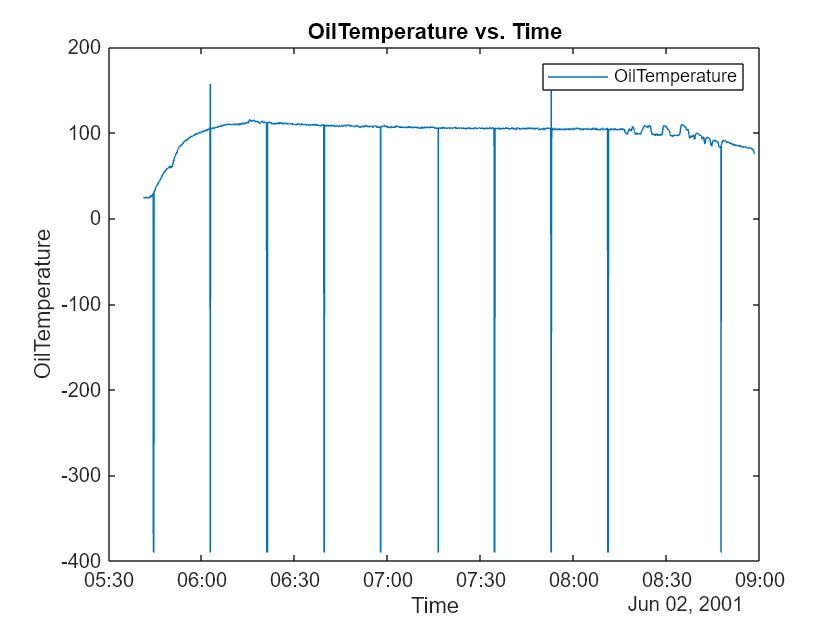

% Create plot of FlightData.Time and FlightData.OilTemperature
h = plot(FlightData,"Time","OilTemperature","DisplayName","OilTemperature");

% Add xlabel, ylabel, title, and legend
xlabel("Time")
ylabel("OilTemperature")
title("OilTemperature vs. Time")
legend

## Step3: Clean

FlightData

FlightData = 47312×13 timetable
           Time            FuelQuantity    OilPressure    OilTemperature    LatitudePosition    LongitudePosition    Altitude    ExhaustTemperature    FuelFlow    FanSpeed    TrueAirSpeed    WindDirection    WindSpeed    WeightOnWheels
    ___________________    ____________    ___________    ______________    ________________    _________________    ________    __________________    ________    ________    ____________    _____________    _________    ______________

    2001-06


FlightData1 = FlightData(FlightData.TrueAirSpeed >= 100,:)

FlightData1 = 42584×13 timetable
           Time            FuelQuantity    OilPressure    OilTemperature    LatitudePosition    LongitudePosition    Altitude    ExhaustTemperature    FuelFlow    FanSpeed    TrueAirSpeed    WindDirection    WindSpeed    WeightOnWheels
    ___________________    ____________    ___________    ______________    ________________    _________________    ________    __________________    ________    ________    ____________    _____________    _________    ______________

    2001-0

% Smooth input data
FlightData2 = smoothdata(FlightData,"movmean","SmoothingFactor",0.25, ...
    "DataVariables",["OilPressure","OilTemperature"]);

% Fill outliers
FlightData2 = filloutliers(FlightData,"linear","movmedian",minutes(1.7), ...
    "DataVariables",["OilPressure","OilTemperature"]);